close("all"); clear; clc;

y1 = [2,7,4,9];
h = [1,0,1];
[y2,r] = deconv(y1,h)

y2 =      2     7


r =      0     0     2     2


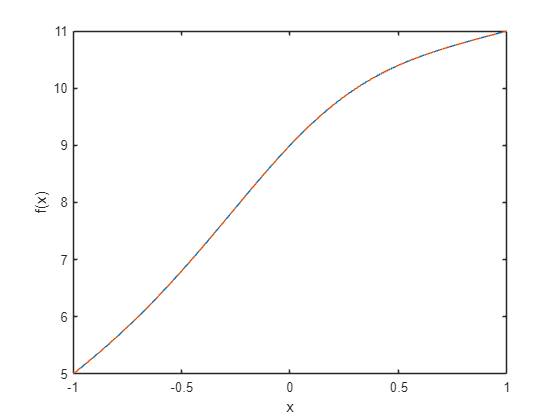

x = linspace(-1,1,100);
f1 = polyval(y1,x)./polyval(h,x);
f2 = polyval(y2,x) + polyval(r,x)./polyval(h,x);

figure()
hold on;
plot(x,f1)
plot(x,f2,'--')
hold off;
box on
xlabel("x");
ylabel("f(x)");

clear;
n = 3;
pa = legpol(n)

pa =     2.5000         0   -1.5000         0


pb = legpol(n-1)

pb =     1.5000         0   -0.5000


num = pa + [0,pb]

num =     2.5000    1.5000   -1.5000   -0.5000


den = [1,1];
[y,r] = deconv(num,den)

y =     2.5000   -1.0000   -0.5000


r =      0     0     0     0


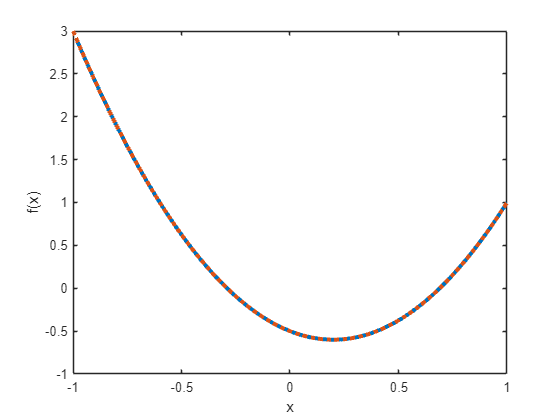


x = linspace(-1,1,100);
f1 = polyval(num,x)./polyval(den,x);
f2 = polyval(y,x);

figure()
hold on
plot(x,f1,"LineWidth",3);
plot(x,f2,':',"LineWidth",3)
hold off
box on
xlim([-1,1]);
xlabel("x");
ylabel("f(x)");